# Fundamental Theorem of Calculus

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

One profound connection between differential and integral calculus is the relationship between [accumulation functions](matlab:open('./Riemann.mlx')) and [derivative functions](https://github.com/MathWorks-Teaching-Resources/Calculus-Derivatives). 

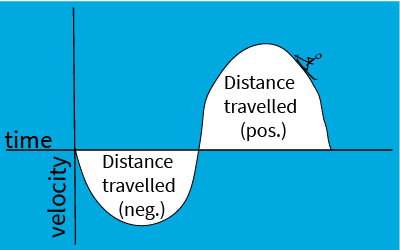

The geometric area under a curve corresponds to the total accumulation of the product of the values tracked along each axis. In this image velocity times time is distance. 

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

## Fundamental Theorem of Calculus, Derivative Form

 
$$\frac{d}{dx}\left[\int_a^x f(t)\; dt \right]$$

$$=\lim_{\epsilon \to 0}\frac{\int_x^{x+\epsilon}f(t)\; dt}{\epsilon} = \lim_{\epsilon \to 0} \frac{f(x)\cdot (x+\epsilon-x)}{\epsilon} = f(x)$$


figure
clear f
syms t
f(t) =  t^2;
a = -2;
x = 3;

To consider a limit as $\epsilon \to 0$, it is important to consider both positive and negative values of `epsilon`. To facilitate a close approach to zero, the slider allows you to set the exponent $n$ in the expression $\epsilon = 10^n$ so the slider presents values from about 1.26 to 1e-8. 

EpsNeg = false;    EpsExp = -1;
epsilon = (-1)^EpsNeg*10^(EpsExp);
tAll = -5:.01:5;
try
    plot(tAll,f(tAll),"-",SeriesIndex="none")
catch
    plot(tAll,f(tAll),"k-")
end
ax = gca;
cmap = colororder;
hold on
if a <= x
    % If integration is left-to-right, color the base area in blue
    tVals = a:.01:x;
    % ColChoice = "#0072BD";
    ColChoice = cmap(1,:);
else
    % If the integration is right-to-left, color the base area in orange
    % and print a warning
    tVals = x:.01:a;
    % ColChoice = "#D95319";
    ColChoice = cmap(2,:);
    warning("You are inverting the direction of integration from left-to-right to right-to-left")
end
leftmax = min(a,x);
rightmin = max(a,x)+.1;

Use these controls to zoom in on your region of interest:

xleft = -5;
xright = 5;
 
% Fix the ExtraArea color to be golden
if EpsNeg
    ColeChoice = cmap(4,:);
else
    ColeChoice = cmap(3,:);
end
% ColeChoice = "#EDB120";
yVals = f(tVals);
tpeVals = linspace(x,x+epsilon,50);
ypeVals = f(tpeVals);
BaseArea = area(tVals,yVals,"FaceColor",ColChoice);
ExtraArea = area(tpeVals,ypeVals,"FaceColor",ColeChoice);
xlim([xleft xright])
fxVal = double(vpa(subs(f,x)));
AreaVal = double(vpa(int(f,t,x,x+epsilon)))/epsilon;
%intfVal = int(f,t,x,x+eps);
TopyVal = ax.YLim(2)+1/20*(ax.YLim(2)-ax.YLim(1));
BottomyVal = ax.YLim(1)-1/10*(ax.YLim(2)-ax.YLim(1));
LeftxVal = xleft+.1*(xright-xleft);
MidxVal = (xleft+xright)/2;
BottomxVal = xleft+.4*(xright-xleft);
text(LeftxVal,TopyVal,"$f(x) = $"+fxVal,"Interpreter","latex")
text(MidxVal,TopyVal,"$\left(\int_x^{x+\epsilon} f(t)\; dt\right)/\epsilon =$ "+AreaVal,"Interpreter","latex")
text(BottomxVal,BottomyVal,"$\epsilon = $"+epsilon,"Interpreter","latex")
hold off

## Fundamental Theorem of Calculus, Antiderivative Form

$\displaystyle F(x) = C+ \int_{c}^x f(t)\; dt$ is the total amount accumulated from any point $c$ up to the point $x$ plus an arbitrary constant $C$. Then the total amount accumulated between $t=a$ and $t=b$ is 


$$\int_a^b f(t)\; dt = \int_{c}^b f(t)\; dt - \int_{c}^a f(t)\; dt = \left(C+ \int_{c}^b f(t)\; dt\right) - \left(C+ \int_{c}^a f(t)\; dt\right) = F(b)-F(a).$$


That is, the amount accumulated between $a$ and $b$ is the total amount that accumulated from the beginning of time up until time $b$ minus everything that had accumulated from the beginning of time up until $a$. 

figure
syms t
f(t) = sin(t);
a = -2;         b = 1;
c = -200;          C = 0;
AreaFlag = false;            
if ~exist("tAll","var")
    tAll = -5:.01:5;
end
syms x
F(x) = int(f,t,c,x);
FAVal = double(subs(F,a)+C);
FBVal = double(subs(F,b)+C);
try
    plot(tAll,f(tAll),SeriesIndex="none")
catch
    plot(tAll,f(tAll),"k-") 
end
ax = gca;
hold on
if a <= b
    % If area is accumulated to the right of a, color the area in blue
    tVals = a:.01:b;
    ColChoice = cmap(1,:);
%    ColChoice = "#00a9e0";
else
    % If the integration is removed to the left of a, color the area orange
    tVals = b:.01:a;
    ColChoice = cmap(2,:);
%    ColChoice = "#004b87";
end
% Fix the extraArea color to be purple
ColeChoice = cmap(4,:);
% ColeChoice = "#7730ba";
yVals = f(tVals);
tpeVals = -5:.01:min(a,b);
ypeVals = f(tpeVals);
OverlapArea = area(tVals,yVals,"FaceColor",ColChoice);
if ~AreaFlag
    ExtraArea = area(tpeVals,ypeVals,"FaceColor",ColeChoice);
end
TopyVal = ax.YLim(2)+1/20*(ax.YLim(2)-ax.YLim(1));
BottomyVal = ax.YLim(1)-1/10*(ax.YLim(2)-ax.YLim(1));
LeftxVal = ax.XLim(1)+.1*(ax.XLim(2)-ax.XLim(1));
MidxVal = (ax.XLim(1)+ax.XLim(2))/2;
BottomxVal = ax.XLim(1)+.4*(ax.XLim(2)-ax.XLim(1));
text(LeftxVal,TopyVal,"$F(b) = $"+FBVal,"Interpreter","latex")
text(MidxVal,TopyVal,"$F(a) = $ "+FAVal,"Interpreter","latex")
text(BottomxVal,BottomyVal,"$F(b)-F(a) = $"+double(int(f,a,b)),"Interpreter","latex")
plot([a a],[min(yVals) max(yVals)],"r-")
plot([b b],[min(yVals) max(yVals)],"r-")
xNL = ["a = "+a "b = "+b "-5" "0" "5"];
[xNameVals,idxA,~] = unique([a b -5 0 5]);
xNameLabels = xNL(idxA);
xticks(xNameVals);
xticklabels(xNameLabels);
hold off

[⇦ Main Menu](matlab:open('MainMenu.mlx'))